# Q2

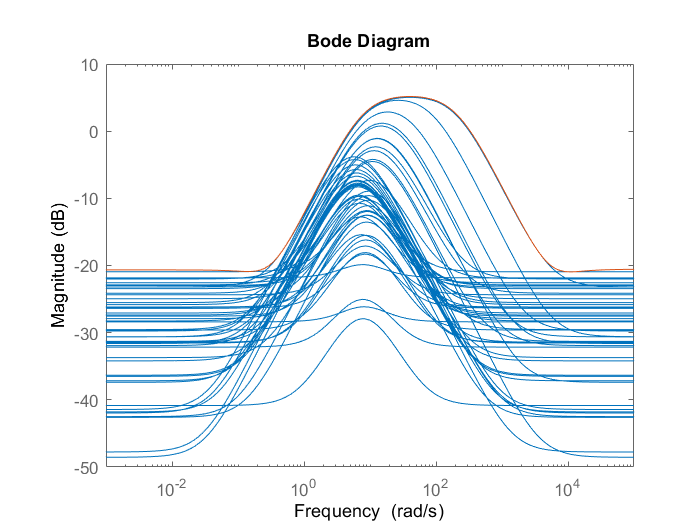

s = tf('s');
K = ureal('K',11,'Range',[10,12]);
tau = ureal('tau',0.25,'Range',[0,0.5]);
% Nominal Rational plant
G0 = K.NominalValue*(-0.5*tau.NominalValue*s + 1)/(0.5*tau.NominalValue*s+1)/(s+1);

G = K*(-0.5*tau*s + 1)/(0.5*tau*s+1)/(s+1);

G_pade_unc = usample(G,50);
[Gp,info] = ucover(G_pade_unc,G0,4);

% Weighting function
bodemag((G_pade_unc-G0)/G0,info.W1);

info.W1

ans =
 
  A = 
               x1          x2          x3          x4
   x1  -4.449e+04        6186   3.842e+04   -1.49e+04
   x2    4.45e+04       -6196  -3.842e+04    1.49e+04
   x3   -4.45e+04        6205   3.841e+04   -1.49e+04
   x4   1.113e+04       -1551       -9601        3716
 
  B = 
               u1
   x1   2.585e+04
   x2  -2.585e+04
   x3   2.585e+04
   x4       -6463
 
  C = 
           x1      x2      x3      x4
   y1   1.592  -1.551  -1.588   6.188
 
  D = 
            u1
   y1  0.09373
 
Continuous-time state-space model.

